clc;   clear;   close all ;
load('HiFi_model_data.mat')		
Ts = 1;
range = [1:5001];

u(:,1) = out.logsout{6}.Values.Data(range); %omega, theta1-2, fan1-2
u(:,2) = out.logsout{9}.Values.Data(range); %omega, theta1-2, fan1-2
u(:,3) = out.logsout{10}.Values.Data(range); %omega, theta1-2, fan1-2
u(:,4) = out.logsout{11}.Values.Data(range); %omega, theta1-2, fan1-2
u(:,5) = out.logsout{12}.Values.Data(range); %omega, theta1-2, fan1-2


%-------------------------------------- 
% NAMES are from documentation diagram

y(:,1) = out.logsout{14}.Values.Data(range,3);    %Tsuc 
y(:,2) = out.logsout{14}.Values.Data(range,1);    %Psuc 

data = iddata(y,u,Ts);


## SS estimation

nx = 2;
% nx = [1:10];
[sys,x0] = ssest(data,nx,'DisturbanceModel','none');

A = sys.A;
B = sys.B;
C = sys.C;
system = ss(A,B,C,0);


## SS transformation

% C*T = eye(2)
T=linsolve(C,eye(2));
system_transform = ss2ss(system,inv(T))

system_transform =
 
  A = 
               x1          x2
   x1  -0.0003161   -0.001608
   x2  -5.764e-05  -0.0002932
 
  B = 
               u1          u2          u3          u4          u5
   x1   -0.004171   -0.008157     0.01149   -0.000904     0.00079
   x2  -0.0003746  -0.0003887   0.0007837   8.676e-05  -8.331e-05
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2  u3  u4  u5
   y1   0   0   0   0   0
   y2   0   0   0   0   0
 
Continuous-time state-space model.



x0 = inv(T)*x0;

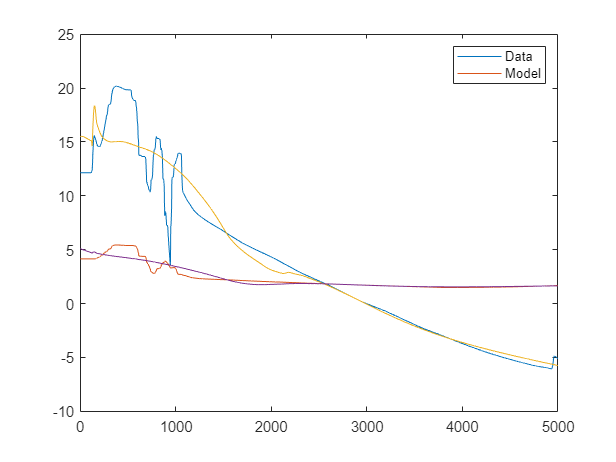

close all
t = 0:Ts:length(range)*Ts-Ts;
[ym,tOut,x] = lsim(system_transform,u,t,x0);

figure(1)
plot(t,y)
hold on
plot(t,ym)
legend("Data","Model")

## MPC setup

Ts = 0.1;      
plant = c2d(system_transform,Ts);

p = 100; % prediction horizon
m = 20;  % control horizon

MV = struct('Min',0,'Max',100);

mpcobj = mpc(plant,Ts,p,m,[],[MV;MV;MV;MV;MV]);
mpcobj.Weights.OutputVariables = [1 1];
% mpcobj.Weights.ManipulatedVariables = [0.5 0.1 0.1 0.1 0.1];
Tsim = 500;
yMPCMOVE = [];
uMPCMOVE = [];

## MPC simulation

close all
% x=[-5.0385;1.2343];
xmpc = mpcstate(mpcobj);
x_mpc = x0;
options = mpcmoveopt;
for ct = 1:round(Tsim/Ts)+1
    % Update and store plant output.
    y_mpc = plant.C*x_mpc;
    yMPCMOVE = [yMPCMOVE y];
    
    
    % Compute control actions and store plant input.
%     u_mpc = mpcmove(mpcobj,xmpc,y_mpc,[-5.0385;1.2343],[],options);
    u_mpc = mpcmove(mpcobj,xmpc,y_mpc,[-5.0385;1.2343],[],options);
    
    uMPCMOVE = [uMPCMOVE u_mpc];
    % Update plant state.
    x_mpc = plant.A*x_mpc + plant.B*u_mpc;
end

figure()
plot(uMPCMOVE')

## LQR

% % % 
% Q=  [   10  0  
%         0  0.1];
% % Q = 1;
% R = [1  0  0  0  0 
% 	    0  1  0  0  0 
% 	    0  0  1  0  0                               
% 	    0  0  0  1  0 
% 	    0  0  0  0  1];
% 
% Q_i = [  7     0     0     0 
%          0     100     0     0 
%          0     0     1     0  
%          0     0     0     10];
% 
% % R = eye(5);
% K   = lqr(system, Q, R);
% K_i = lqi(system, Q_i, R);
% integral_states = [900;100];
% K_i*[x(end,:)' ; integral_states]
% 
% eig(A);
% 
% obs_pole = [-50 -60];
% 
% L=place(A',C',obs_pole)';
